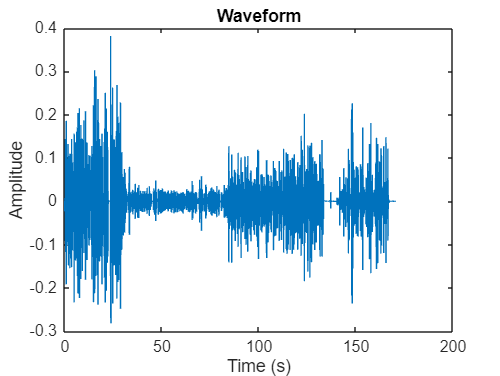

[x, Fs] = audioread('mix.wav');

t = (0:length(x)-1)/Fs;
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform');

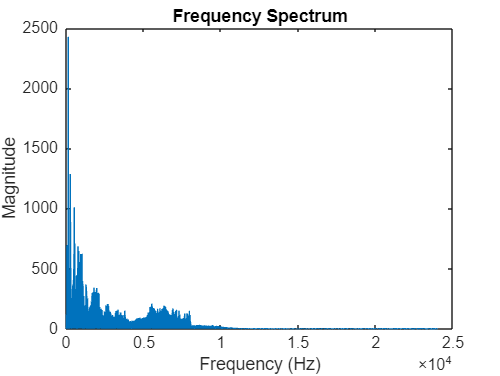


N = length(x);
X = fft(x);
f = Fs*(0:N/2-1)/N;
magnitude = abs(X(1:N/2));
plot(f, magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum');

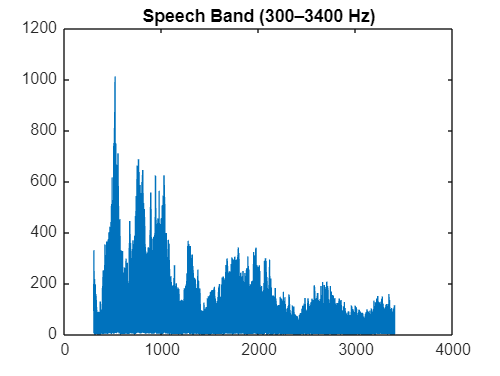


speech_band = (f >= 300 & f <= 3400);
plot(f(speech_band), magnitude(speech_band));
title('Speech Band (300–3400 Hz)');